# MR Signal Equations

Pulse sequences create an MR signal that depends on the specific parameters used for that sequence.  For several important pulse sequences, we have equations that describe the size of the signal we expect, given the parameters.  This tutorial describes and plots some of the signals.

This tutorial goes through the sequences and the equations for major types of acquisitions.

## Spin Echo

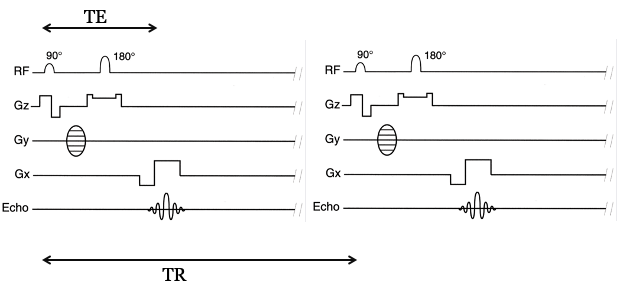

The key variables for the spin echo sequence are:  TR, T1, T2


$$\mathrm{signal}\left(\mathrm{SE}\right)=\left(1-\exp \left(-\frac{\mathrm{TR}}{\mathrm{T1}}\right)\right)\exp \left(-\frac{\mathrm{TE}}{\mathrm{T2}}\right)$$


## Calculating the Spin Echo signal

TR = 2;   % sec
T1 = 1.1; % sec
TE = (0.02:0.02:0.40);  % 20 ms to 400 msec


## Gradient Echo

The Gradient Echo Sequence has this pulse diagram

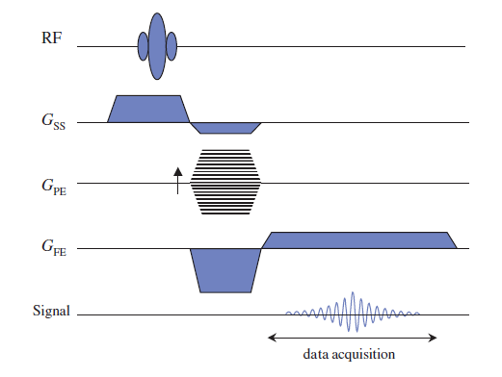

The key parameters for the sequence are the flip angle $$\alpha$$, TR, TE, T1 and T2*.  The formula is


$$Signal(GE) = M_0 {\frac{sin(\alpha) (1 - exp^{(-TR/T1)} )e^{(-TE/T2*)}}{1 - cos(\alpha)(1 - exp^{-(TR/T1)})}$$


## Calculating the GE signal

We can write the parameters and Matlab expression this way

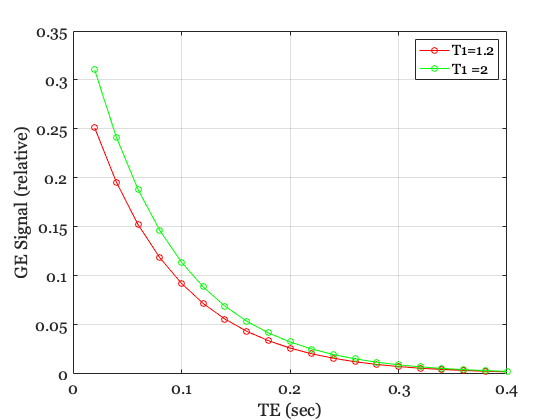

M0 = 1;      % To ignore, treating as relative
FA = 60;     % deg
TR = 1;      % sec
T1 = 1.2;    % sec
T2star = 0.08;  % sec

% Sweep out a set of measurement times for the graident echo
TE = (0.02:0.02:0.40);  % 20 ms to 400 msec

% sind is sine for degree inputs
% The Gradient Echo Signal Equation
sig = sind(FA)*(1 - exp(-TR/T1))*(exp(-TE/T2star)) / ...
    (1 - cos(FA)*1 - exp(-TR/T1));

figure; 
plot(TE,sig,'-o');
grid on;

hold on;
TR = 2;
sig = sind(FA)*(1 - exp(-TR/T1))*(exp(-TE/T2star)) / ...
    (1 - cos(FA)*1 - exp(-TR/T1));
plot(TE,sig,'-o');
legend({'T1=1.2','T1 =2'})
xlabel('TE (sec)'); ylabel('GE Signal (relative)');

## [Spoiled Gradient Echo Recalled](https://mriquestions.com/spoiling---what-and-how.html)

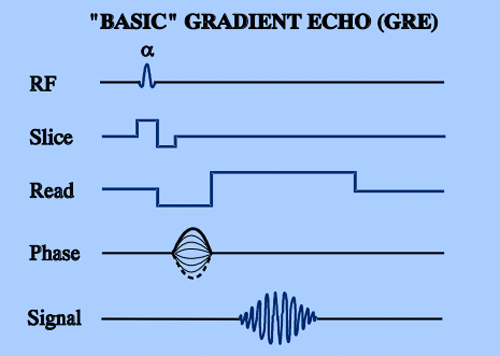 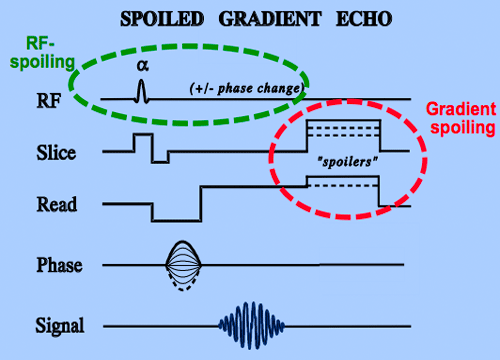

## Inversion Recovery